# **シミュレーションの条件設定一覧**

**power_networkクラスのシミュレーションを行うには、net.simulateメソッドを実行します。メソッドの引数は、シミュレーション時間と、条件設定の変数名と値のセットを引き渡します。**

**本ページでは、各条件設定のvarとvalueの書き方を解説します。**

**本ファイルで行う作業行程の対応箇所**

## 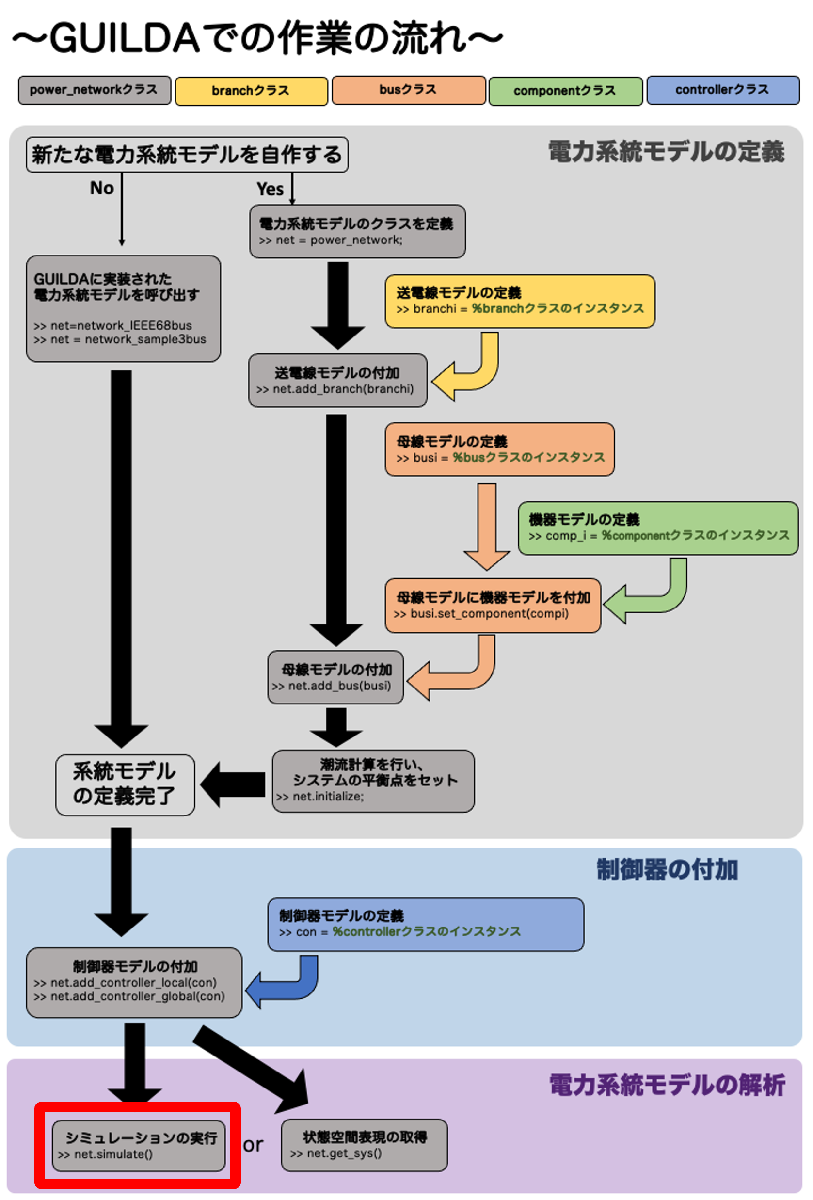

# **初期値の設定**

 
net_init   = network.IEEE14bus;
event_init = odeEventSet("init",net_init,"OffsetUnit","SG1B001","OffsetState",["delta";"Eq"],"OffsetValue",[pi/6;0.1]);
sol_init   = net.simulate([0,50],event_init);

# **地絡応答**

## **・実行方法**

 
net_fault   = network.IEEE14bus;
event_fault = odeEventSet("fault",net_fault,"FaultBus","B008","TimeSpan",[3,3.01]);
sol_fault   = net.simulate([0,50],event_fault,"AbsoluteTolerance",1e-6,"RelativeTolerance",1e-6);

# **入力応答**

## **・実行方法**

 
net_input   = network.IEEE14bus;
event_input = odeEventSet("input",net_input,"InputUnit","LPQ1B013","InputName",["P";"Q"],"InputValue",[-0.5,0.2],"TimeSpan",[3,3.5]);
sol_input   = net_input.simulate([0,50],event_input,"AbsoluteTolerance",1e-6,"RelativeTolerance",1e-6);

# **解列・並列**

## **・実行方法**

### **　・機器の解列**

 
net_trip   = network.IEEE14bus;
event_trip = odeEventSet("trip",net_trip,"TripUnit","LPQ1B012","TimeSpan",[10,50]);
sol_trip   = net_trip.simulate([0,50],event_trip);

### **　・ローカルコントーラの解列**

% これはTODOです

### **　・グローバルコントーラの解列**

% これはTODOです

# **複数の時間イベントを指定したシミュレーション**

# **GridCodeによるイベント検出**

% ToDo

# **リアルタイムでの応答プロット**

## **・プロットするパラメータの指定**

 
net = network.Tutorial3bus;
p   = struct('para', 'omega', 'index', [], 'axisID', 1);
p(2)= struct('para', 'P'    , 'index', 1:3, 'axisID', 2);

out = net.simulate( [0,5], 'OutputFcn', p, 'simulate_when_disconnect',true);

# **進行度の表示**

## **・ダイアログで表示**

ライブスクリプト上で実行するとエラーが出るため、以下のコードを「コマンドウィンドウ」上で実行

net = network.Tutorial3bus;
out = net.simulate([0,10],'report','dialog');

## **・コマンドウィンドウで表示（デフォルト）**

 
net = network.Tutorial3bus;
out = net.simulate([0,10],'report','disp');

## **・表示しない**

 
net = network.Tutorial3bus;
out = net.simulate([0,10],'report','none')

# **シミュレーションの制限時間**

## **・制限時間を設けない（デフォルト）**

 
net = network.Tutorial3bus;
timelimit = inf;
out = net.simulate([0,50],'fault',{{[1,50],1}},'time_limit',timelimit);

## **・制限時間を設ける**

 
net = network.Tutorial3bus;
timelimit = 10;
out = net.simulate([0,50],'fault',{{[1,50],1}},'time_limit',timelimit);

# **近似線形システムでのシミュレーション**

## **・近似線形化モデルでのシミュレーション**

out = net.simulate([0,10],'linear',true);

# **ODEソルバーのオプション**

## **・相対許容誤差**（"odeset"の公式ドキュメントを参照）

val = 1e-8;
out = net.simulate([0,10],'RelTol',val);

## ・絶対許容誤差（"odeset"の公式ドキュメントを参照）

val = 1e-8;
out = net.simulate([0,10],'AbsTol',val);

## ・式の最大次数（"odeset"の公式ドキュメントを参照）

val = 3;
out = net.simulate([0,10],'MaxOrder',val);

# **電力ネットワークモデルの定義**

### **今回の演習では以下の画像に示すような「IEEE14busモデル」と呼ばれる系統モデルを解析対象にしてみます**

## **IEEE 14bus モデル**

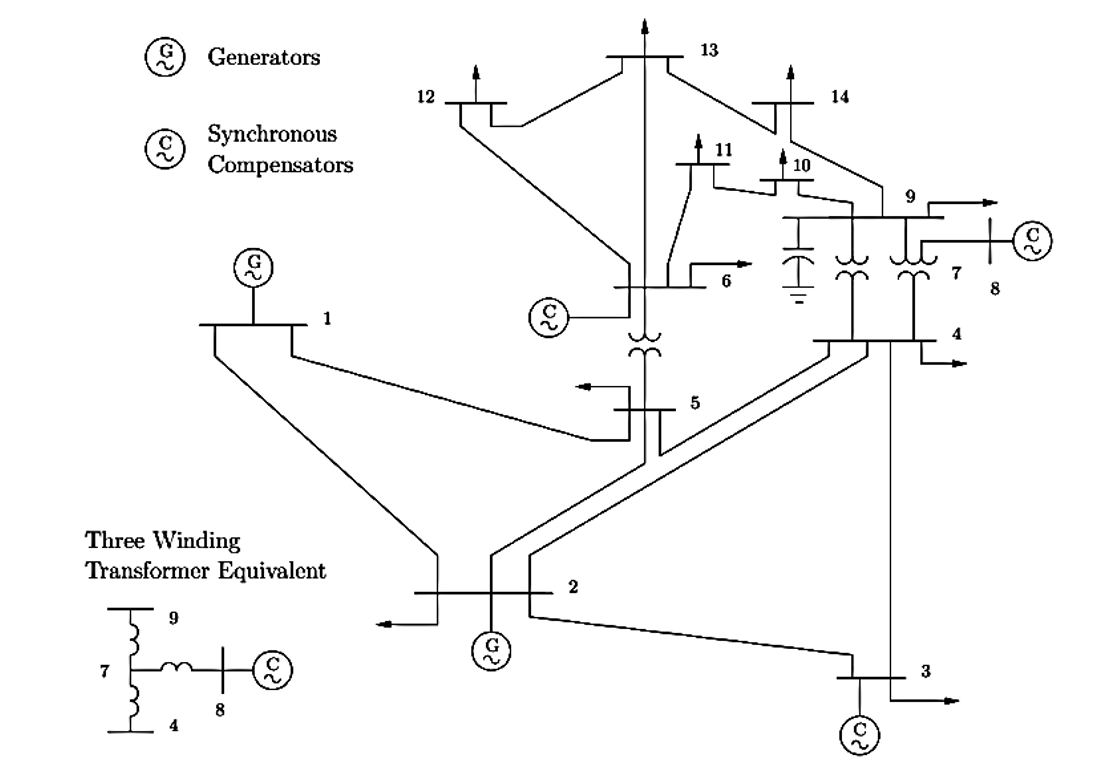

- 母線は全部で14個

- 母線1,2には同期発電機モデルが接続

- 母線3,6,8には同期調相機を接続

- 母線5-6,母線4-9,母線4-7-9の間に変圧器を接続

#### GUILDAに実装済みの標準モデルは以下のボタンから呼び出すことができます !!

net_origin = network.IEEE14bus; 
disp("IEEE14母線系統を読み込みました.")
base_bus = net_origin.a_Bus([3,9,12,14]);
INV_past = repmat(2,[1,4]);
base_comp_name = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];

# **IEEE 14母線系統図の構成と読み方**

#### **本スクリプトでは、電力系統解析の標準モデルであるIEEE 14母線系統を対象としたシミュレーションを行います。解析を開始する前に、系統図に描かれている各シンボルやネットワーク構造の読み方を整理します。**

## **# 主要な構成要素とシンボル**

#### **系統図内にある各マークや数字は、以下の電力設備およびシステム要素を表しています。**

#### **・母線（Bus）：1から14の数字**

図中の太い横線または縦線は母線（Bus）を表し、それぞれ1から14までのインデックスが割り振られています。電力流（潮流）計算においては、これらはそのノード（接続点）の電圧、位相角、注入電力を定義する基準となります。

#### **・発電機（Generator）：Gマーク**

設置箇所は母線1と母線2です。系統に有効電力と無効電力を供給する、伝統的な大型の同期発電機です。通常、潮流計算において最も容量の大きい母線1はスラック母線（基準母線）として指定され、母線2はPV母線（電圧制御母線）として扱われます。

#### **・同期調相機（Synchronous Compensator）：Cマーク**

設置箇所は母線3、母線6、母線8です。有効電力（出力）を持たず、回転体を空転させることで無効電力の調整能力だけを提供する設備です。潮流計算の条件としては、発電機と同様に電圧を一定に保つPV母線（ただし有効電力 P = 0）としてモデル化されます。

#### **・負荷（Load）：外側を向いた矢印**

設置箇所は母線2, 3, 4, 5, 6, 9, 10, 11, 12, 13, 14です。その母線から外部（電力消費地）へ流れ出る需要（負荷電力）を示しています。

#### **・進相コンデンサ（Capacitor）**

設置箇所は母線9です。地面に接地されている並列コンデンサです。系統の電圧を維持・改善するために固定の無効電力を注入します。

## **# 有効電力と無効電力の物理的意味**

本系統の解析やブラックアウト現象を理解する上で、有効電力（P）と無効電力（Q）の役割を区別することが極めて重要です。

有効電力は、実際に負荷で消費されて仕事（熱、光、動力など）に変換される電力です。主に発電機のタービン（原動機）から供給され、系統全体の周波数と密接に結びついています。需要に対して有効電力が不足すると系統の周波数が低下し、最悪の場合は周波数崩壊によるブラックアウトを招きます。

無効電力は、交流系統のインダクタンス（送電線やモータのコイルなど）に磁界を形成するために行き来するだけで、消費されない電力です。しかし、送電網の「電圧」を一定に維持するために不可欠な存在です。無効電力が不足すると系統の電圧が維持できなくなり、連鎖的な電圧低下から電圧崩壊（ブラックアウト）を引き起こします。系統図にある同期調相機や進相コンデンサは、この無効電力を局所的に補給して電圧を支える重要な役割を担っています。

## **# 変圧器の接続関係と3巻線変圧器の等価回路**

#### **母線4、5、7、9の間にあるうずまきのマークは変圧器（Transformer）です。**

#### **特に、左下に拡大図として示されている「Three Winding Transformer Equivalent（3巻線変圧器等価回路）」に注目してください。母線4（下側）と母線9（上側）を結ぶ送電ルートの途中に母線7があり、そこから分岐して母線8に接続されている同期調相機へ電力を供給しています。これは、1台の変圧器から3つの異なる電圧（あるいは回路）を取り出す「3巻線変圧器」のインピーダンス特性を、電気回路上のスター結線ネットワークとしてモデル化していることを示しています。**

# **系統の構成をいじってみよう !!**

## **図のように母線3,9,12,14ではGFM,GFLの選択ができるようになっています。**

## **自由に機器を選択して、系統の挙動がどのように変わるのか確認してみましょう。**

**※まずは、デフォルトの系統で実験してみることをお勧めします !!**

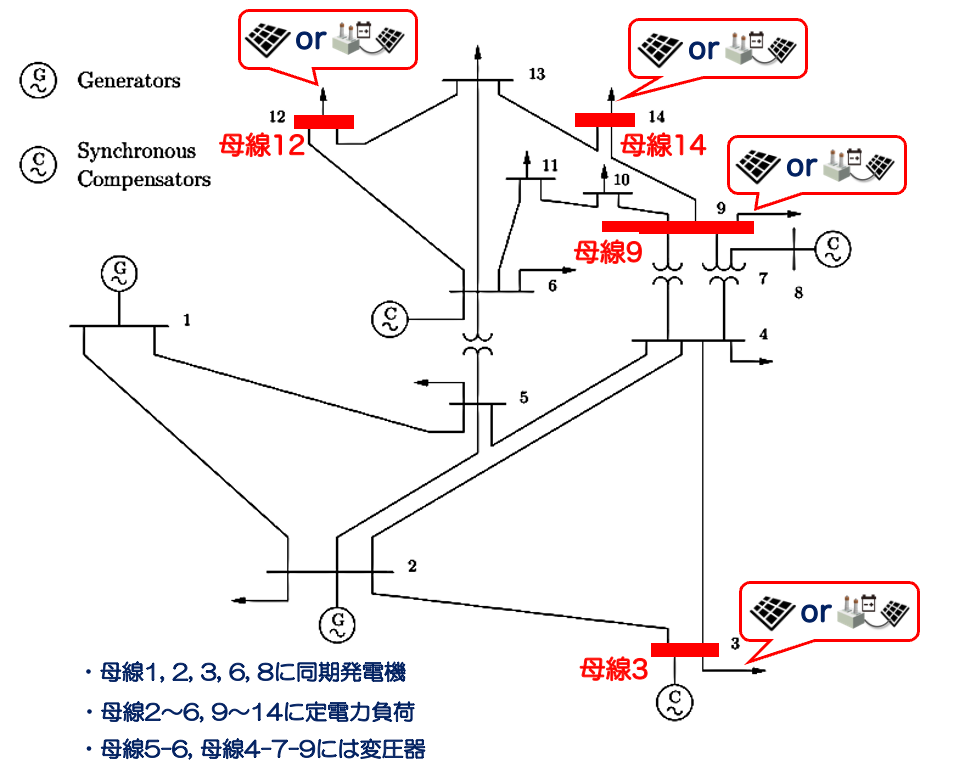

INV1 = 1;
INV2 = 2;
INV3 = 1;
INV4 = 2; 

inv_list = [INV1;INV2;INV3;INV4];

cmp_list = ["gen-classical";"load-power"];

tab_param = table(10,20,0.65,0.34, 'VariableNames', {'M','D','Xd','Xq'});
for inv = 1:numel(inv_list)
    if INV_past(inv) ~= inv_list(inv)
        % 変更する機器の名前
        base_name = base_comp_name(inv);
        % 新しく接続する機器
        new_comp  = cmp_list( inv_list(inv) );

        str_tagComp = string(base_bus{inv}.a_Component);

        % 機器を新しいものに付け替える
        base_bus{inv}.replace_component(base_name, new_comp,tab_param );    

        % 母線に接続されている機器のタグ
        l_new_tag = string(base_bus{inv}.a_Component);

        % 変更された機器のタグを取得
        comp_tag = l_new_tag(l_new_tag~=str_tagComp);
        base_comp_name(inv) = comp_tag;

        INV_past(inv) = inv_list(inv);
    end
end

net_origin.initialize;
disp("変更が反映されました。実験に移りましょう !!")

# **シミュレーションの実行**

## **地絡や解列を通して系統の挙動を数値的に観察してみましょう !!**

**※ 設定によっては解けない可能性があります。その場合は設定を変えてみましょう。**

# **a) 需要変動**

## **・需要変動シミュレーションの概要**

本シミュレーションでは、系統内の負荷（電力需要）を動的に変化させた際の、系統全体の応答特性を解析します。電力系統が安定して運用されるためには、発電量（供給）と負荷量（需要）が常に一致していなければなりません。この需給バランスの変動は、系統の周波数変化として直接現れます。

### # 需要が増加した場合の挙動

系統全体の負荷が突発的に増加すると、発電機の供給力が不足します。このとき、同期発電機の回転体（タービンとロータ）に蓄えられている運動エネルギーが消費されるため、回転速度がブレーキをかけられたように一斉に低下します。発電機の回転速度は系統周波数と直結しているため、結果として系統全体の周波数が低下します。

### # 需要が減少した場合の挙動

逆に、工場や家庭での電力消費が急激に減少するなどして負荷が減ると、系統内は発電過剰の状態になります。余ったエネルギーは発電機の回転体を加速させる方向に働くため、回転速度が上昇し、系統全体の周波数が上昇します。

input_bus       = 13;
input_state = "Pload";
input_value = 0.05;
input_time = 17;
input_simulation_time = 64; 

input_component = 1;
if input_component > numel(net_origin.a_Bus{input_bus}.a_Component)
    
    disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
         "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return    
end
COMP_input = net_origin.a_Bus{input_bus}.a_Component{input_component};
stru = COMP_input.str_u;

if input_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if isa(COMP_input, 'component.generator.abstract')
    if ~ismember(input_state, COMP_input.str_u)
        disp(" >> どうやら負荷の入力を選択しているようですね。" + newline + ...
             "    同期機への入力はタービンからの入力である Pmech と励磁機からの入力である Vfield です。" + newline + ...
             "    これら二つの内、どちらか一方を選択してみましょう !!")
        return
    end
elseif isa(COMP_input, 'component.load.abstract')
    if ~ismember(input_state, COMP_input.str_u)
        disp(" >> どうやら同期機の入力を選択しているようですね。" + newline + ...
             "    負荷への入力は有効電力である Pload と無効電力である Qload です。" + newline + ...
             "    これら二つの内、どちらか一方を選択してみましょう !!")
        return
    end
end

ev_input = odeEventSet("ev_input", net_origin, "TimeSpan", [0, input_time], "InputUnit", COMP_input.str_tag, "InputName", input_state, "InputValue", -input_value);
sol_input = net_origin.simulate([0, input_simulation_time], ev_input);

xsol_input = sol_input.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_input.t, xsol_input.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

# **b) 地絡**

## **・地絡事故応答シミュレーションの概要**

**電力系統における代表的な事故形態である、送電線の地絡事故が発生した際の系統の過渡応答特性を解析します。落雷などが原因で送電線が大地と短絡する地絡事故は、周波数の変動だけでなく、系統の「電圧」や「同期安定性」に極めて大きな影響を与えます。**

### **# 地絡事故発生時の挙動**

事故が発生した瞬間、事故点周辺の電圧は急激に低下します（瞬時電圧低下）。電圧が低下すると、発電機から系統へ電気を送り出すことが難しくなり、発電機の電気的出力が急減します。一方で、機械的な入力（タービンを回す力）はすぐには変化できないため、余ったエネルギーによって発電機の回転体が急速に加速し、位相角が拡大します。

### **# 事故除去と過渡安定度**

事故が発生すると、系統の保護リレーが異常を検知し、遮断器によって事故の起きた送電線を瞬時に系統から切り離します（事故除去）。事故が除去されると電圧は回復に向かいますが、加速してしまった発電機が元の同期運転を維持できるか、あるいは同期を維持できずにばらばらに暴走してしまうか（脱調）が、過渡安定度解析における重要な評価項目となります。

fault_bus = 8;
fault_simulation_time = 48;
fault_start_time = 25;
fault_time = 0.03; 

FBUS_tag = net_origin.a_Bus{fault_bus}.str_tag;
ev_fault = odeEventSet("ev_fault", net_origin, "TimeSpan", [fault_start_time, fault_start_time+fault_time], "FaultBus", FBUS_tag);
sol_fault = net_origin.simulate([0, fault_simulation_time], ev_fault);

xsol_fault = sol_fault.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_fault.t, xsol_fault.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

# **c) 解列**

## **・発電機および負荷の解列シミュレーションの概要**

**解列とは、異常が発生した発電機や送電線、あるいは一部の需要家（負荷）を電力網（系統）から切り離す遮断操作のことです。系統全体の完全な崩壊（ブラックアウト）を防ぐため、保護リレーなどの制御システムがどのような基準で解列を判断するかを整理します。**

### **# 発電機を解列させるケース**

系統内の主要な発電機は、自らの設備が致命的なダメージを受けるリスクがある場合、または周囲の状況から運転継続が不可能と判断された場合に自動的に系統から解列します。代表的な要因として、事故による系統周波数の過度な低下や上昇、電圧が限界を超えて低下する電圧崩壊、落雷時の激しい電圧変動にインバータ電源が耐えきれなくなるケース、そして発電機間の同期が完全に崩れる脱調現象などが挙げられます。

### **# 負荷を解列させるケース**

一方で、系統を守るためにあえて需要家側を強制的に切り離す「負荷遮断」という過渡制御も存在します。大型の発電所が突発的に脱落した際、残された発電機だけでは需要を支えきれず、周波数が坂道を転げ落ちるように急低下します。このとき、周波数が発電機の解列ラインに達する前に、不足周波数リレー（UFR）などが作動して一部の地域の負荷をあえて強制停電（解列）させることで、需給バランスを瞬時に一致させ、系統全体の全滅を未然に防ぎます。

trip_bus = 2;
trip_component = 2;
trip_simulation_time = 50;
trip_start_time = 11;
trip_time = 5.91; 

TBUS = net_origin.a_Bus{trip_bus};
NumOfComp = numel(TBUS.a_Component);

if trip_component > NumOfComp
    if ~isa(net_origin.a_Bus{trip_bus}.a_Component{end}, 'component.load.abstract')
        disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
             "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
             "    上記の系統図を参考に設定を見直してみましょう !!")
        return
    end    
end

if trip_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end



if isscalar(net_origin.a_Bus{trip_bus}.a_Component)
    TCOMP = net_origin.a_Bus{trip_bus}.a_Component{1};
    if isa(TCOMP, 'component.generator.abstract')
        if trip_component == 2
            disp(" >> どうやら負荷を選択しているようです。" + newline + ...
                 "    この母線、実は同期機しか接続されていないんです。" + newline + ...
                 "    設定をもう一度見直してみましょう !!")
            return
        end
    elseif isa(TCOMP, 'component.load.abstract')
        if trip_component == 1
            disp(" >> どうやら同期発電機か同期調相機を選択しているようですね。" + newline + ...
                 "    この母線、実は負荷しか接続されていないんです。" + newline + ...             
                 "    設定をもう一度見直してみましょう !!")
            return
        end
    end
else
    TCOMP = net_origin.a_Bus{trip_bus}.a_Component{trip_component};
end

TCOMP_tag = TCOMP.str_tag;

ev_trip = odeEventSet("ev_trip", net_origin, "TimeSpan", [trip_start_time, trip_start_time+trip_time], "TripUnit", TCOMP_tag);
try
    sol_trip = net_origin.simulate([0, trip_simulation_time], ev_trip);
catch ME
    disp(" >> このシミュレーション設定ではソルバーが解を出せないようです。" + newline + ...
         "    もう少し優しくしてあげてください。お願いしますっっ !!")
end

xsol_trip = sol_trip.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol_trip.t, xsol_trip.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

## 応答結果の見方

上のグラフは周波数偏差($\omega$:omega)の応答になります．

周波数偏差の単位は p.u. です．

電力系統の交流電源は関西では60Hz, 関東では50Hzで運用されています．

例えば60Hzで運用されている系統で周波数が61Hzとなっている場合，周波数偏差は以下のようになります．


$$\frac{61{\rm [Hz]}- 60{\rm [Hz]}}{60{\rm [Hz]}}=0.016 [pu]$$


つまり上の応答は0であることが望ましいということになります．

**余力がある人は以下のコンテンツにも取り組んでみてください**

# **＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝**

# **[おまけ]　GUILDAマスターを目指そう !!**

# **＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝**

ここからは各自で自由にイベントを発生させてみましょう。

まずは以下のコマンドで、スクリプトファイルを開きましょう。

空のスクリプトファイルが表示されましたね。

そしたら以下のコードをファイルの先頭に記述してください。      

これで例のIEEE14母線系統を呼び出すことができました。

ではイベントの定義に移りましょう。イベントはodeEventSetクラスをインスタンス化することによって生成できます。

その際に、自分が発生させたい任意のイベントを指定することができます。

ここでは試しに二番目の母線に接続されている負荷を一定時間増加させてみましょう。

「おいおい、引数が多すぎて目が回るよ！」という声が聞こえてきそうですね。一つずつ解説していきましょう。

- 第一引数

              これは発生させるイベントの名前です。️どんな名前にするかはあなたの自由です.。

- 第二引数

              これは、解析対象の電力系統です。先ほど呼び出したIEEE14busくんのことです。

- オプション1

              これは、イベントが発生する時間帯です。今の例だと0~10秒までイベントが発生するという設定になっています。

- オプション2

             これはイベントを発生されるコンポーネントの名前です。今は母線2に接続された負荷が指定されています。

             ちなみに機器の名前ですが、以下のコマンドで確認することができます。

               今は、入力応答を考えているので、オプションとして "InputUnit" を指定しています。もちろんこれ以外にも下記のようなオプションがあります。

- オプション3

              これは、入力を加える変数を指定しています。例えば今だと母線2の負荷に入力を加えていますが、入力を加える対象には有効電力と無効電力があります。

              今の場合だと"Pload"なので有効電力に入力を加えていることになります。もちろんこれ以外にも以下のようなオプションがあります。

- オプション4

              キター !!、ついに最後のオプションです。

              これは実際にどのような入力を加えるのかを指定しています。今の例だと f(t,x) = 0.1×t^2 - 1という関数を入力しています。

              matlabだと@というシンボルを使うことによって、時間と状態変数の関数として指定できます。

             入力は複数指定することも可能です。しかし、関数ハンドル(@を使った関数)を複数指定する際にはセル配列を使って指定してください。以下に例を示します。

ここまで、一イベントを指定する方法に関して見てきました。

しかし、皆さんの中には「これじゃあ物足りない、最低でも5個は欲しい」という人もいるんじゃないでしょうか？

そんな人のために、5つのイベントアンハッピーセットを作成しました !!

さあ、ここまできたらこれらのイベントを反映したシミュレーションを実行してみましょう。

え？イベントが多すぎて大変だって？

ご安心ください。以下のコードを書くだけで大丈夫です。

一番目の引数にはシミュレーション時間を指定します。今だったら50秒間シミュレーションしたいので[0,50]と指定します。

二番目の引数には想定する時間イベントを指定します。今回はセル配列に格納して一気に展開していますが、もちろん一個一個指定することも可能です。

simulateメソッドを実行することで、ソルバーが解を出してくれます。たまにソルバーが解を出せなくてエラーや警告を出しますが、それもシミュレーションの醍醐味です。

ソルバーの出してくれた解はodeSimulationResultクラスに格納されています。実際に数値を見たい時には

と打つことによって母線と機器ごとに整理されたシミュレーション結果を取得できます。

試しに、母線2に接続された同期発電機の周波数を取得してみましょう。以下のコマンドを実行すればOKです。

では実際に、同期発電機及び同期調相機の周波数をプロットしてみましょう。

プロットは、以下のコードで実行できます。

おめでとうございます！これであなたも、電力系統を手のひらで転がす**一人前のGUILDA使い**です！

net = network.IEEE14bus;

o = cell(5,1);
o{1} = odeEventSet("ev1", net, "TimeSpan",        3, "OffsetState", "delta", "OffsetUnit", "SG1B001", "OffsetValue", pi/6);
o{2} = odeEventSet("ev2", net, "TimeSpan", [ 8,10.5], "InputUnit", "SG1B002", "InputName", ["Pmech";"Vfield"], "InputValue", {0.7; @(t)sqrt(t)*0.1+1});
o{3} = odeEventSet("ev3", net, "TimeSpan", [14,15.0], "InputUnit", "LPQ2B002", "InputName", ["Pload";"Qload"], "InputValue", {@(t) 0.1*t^2-0.2*t+1; @(t) 0.1*sqrt(t)*0.1});
o{4} = odeEventSet("ev4", net, "TimeSpan", [ 8,8.02], "FaultBus", "B008");
o{5} = odeEventSet("ev5", net, "TimeSpan", [ 9,11.0], "TripUnit", "LPQ2B003");

sol = net.simulate([0,50], o{:});

xsol = sol.odeResults;
figure
hold on
arrayfun(@(i) plot(xsol.t, xsol.Bus(i).Component(1).X.omega), [1,2,3,6,8]);

grid on
xlabel("time [s]")
ylabel("omega [p.u.]")

**ちなみに上のグラフは、上記5つのイベントを発生させたときのシミュレーション結果になります。**

# **次に、GFM・GFL最適選択にチャレンジしてみましょう !!**

# 付録:

## １．出力結果のデータ構造

        によって出力されたデータ "out" にはシミュレーションの様々な解析結果が格納されています．

        今回解析を行いたい各発電機の周波数偏差('omega')の時系列データは

        とすることで得られます．

        一方でシミュレーション中のサンプリング時間のデータは以下のようにして取得することが出来ます．

        つまり，例えば以下のように実行することで発電機1の周波数偏差の応答をプロットすることが出来ます！

% function L2 = culculate_l2norm(str)
%     L2 = zeros(1,5);                       %データ格納用の行列を定義
%     fprintf('\n各発電機の周波数偏差のL２ノルム(大きい順) \n\n')
% 
%     c_num = [1,2,3,6,8];
%     %IEEE68busは母線1~16に同期発電機が付加されている．
%     for i = 1:numel(c_num)    
%         t        = str(c_num(i)).t;
%         omega_i  = str(c_num(i)).X{1}.omega;       % 母線iの周波数偏差の応答データを抽出
%         omega2_i = omega_i.^2;              % 応答データの各要素を２乗する
%         integer  = trapz(t, omega2_i);      % ２乗したデータを数値積分する
%         L2_i     = sqrt(integer);           % 積分値の平方根を取りL２ノルムを計算
%         L2(i)    = L2_i;                    % 得られたL2ノルムを配列に格納する
%     end
%     [~, idx_sort] = sort(L2,'descend');     %L2ノルムの大きい順にソートした機器の番号を得る
% 
%     strstr = {'同期発電機','同期発電機','同期調相機','同期調相機','同期調相機'};
%     for i = idx_sort
%         disp([strstr{i},num2str(i,'%.2d'),'のl2ノルム: ',num2str(L2(i))])
%     end
% end
% 
% 





# **0) 初期値応答**

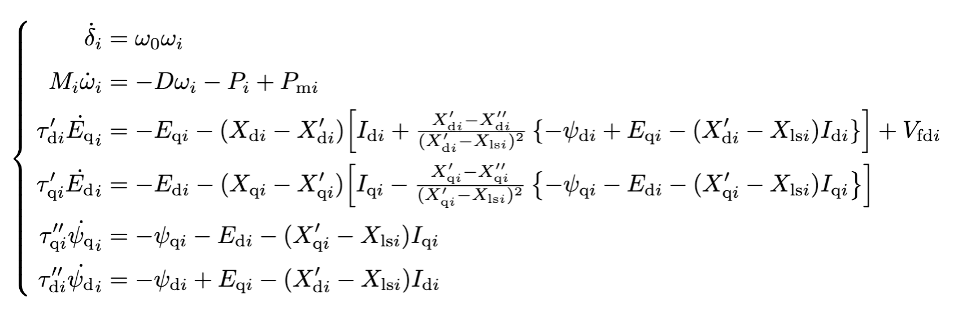

% offset_bus       = 1;
% offset_component = 1;
% offset_state = "delta";
% offset_value = 0.6;
% offset_simulation_time = 42; 
% 
% COMP_offset = net_origin.a_Bus{offset_bus}.a_Component{offset_component};
% strx = COMP_offset.str_x;
% 
% if offset_component > numel(net_origin.a_Bus{offset_bus}.a_Component)
%     disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
%          "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
%          "    上記の系統図を参考に設定を見直してみましょう !!")
%     return
% end
% 
% if offset_bus == 7
%     disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
%          "    上記の系統図を参考に設定を見直してみましょう !!")
%     return
% end
% 
% if isempty(strx)
%     disp(" >> 定電力負荷を選択しているようです。" + newline + ...
%          "    定電力付加には状態変数が存在しません。"+ newline + ...
%          "    上記の系統図を参考に同期発電機、もしくは同期調機を選択してみましょう !!")
%     return
% end
% 
% ev_offset = odeEventSet("ev_offset", net_origin, "TimeSpan", 0, "OffsetUnit", COMP_offset.str_tag, "OffsetState", offset_state, "OffsetValue", offset_value);
% sol_offset = net_origin.simulate([0, offset_simulation_time], ev_offset);
% 
% xsol_offset = sol_offset.odeResults;
% figure
% hold on
% arrayfun(@(i) plot(xsol_offset.t, xsol_offset.Bus(i).Component(1).X.omega), [1,2,3,6,8]);
% 
% grid on
% xlabel("time [s]")
% ylabel("omega [p.u.]")


`本Stepでは、電力系統モデルの応答シミュレーションの各種実行方法を解説しました。`

`次のステップでは得られた応答結果の閲覧方法について解説します。`

[](matlab:open('./Step3_NetProperties.mlx'))　　[](matlab:open('./Step5_SimulateResultData.mlx'))